# **SISTEMAS DE CONTROL DISCRETO                                **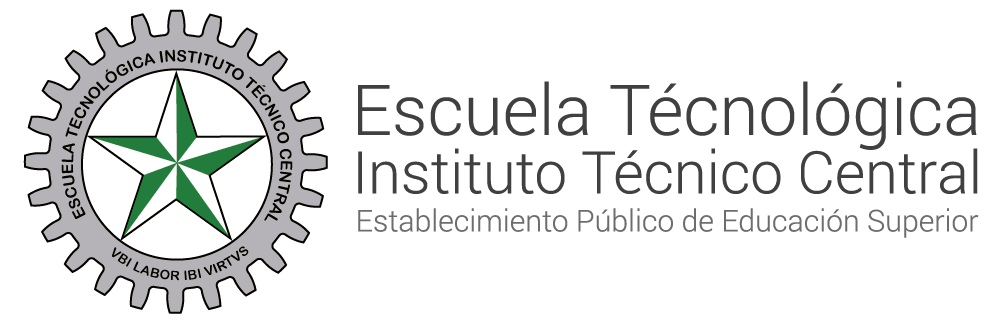

# **Solución ecuaciones diferenciales **

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c

#### OBJETIVO

Repasar el concepto de representación de sistemas mediante la transformada de Laplace así como la **solución de ecuaciones diferenciales**, para analizar y diseñar sistemas de control en el dominio del tiempo continuo.

#### Ejercicio

Resolver y graficar


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }y\left(t\right)+3\frac{{\mathrm{d}}^1 }{\mathrm{d}t^1 }y\left(t\right)+2y\left(t\right)=5u\left(t\right)$$


con condiciones iniciales 


$$\left\lbrack \begin{array}{c}
y\left(0\right)=-1\\
y^1 \left(0\right)=2
\end{array}\right\rbrack$$


## SOLUCIÓN

#### PASO 1

recordando que por definición, la transformada de laplace de una derivada esta dado por la siguiente expresión:

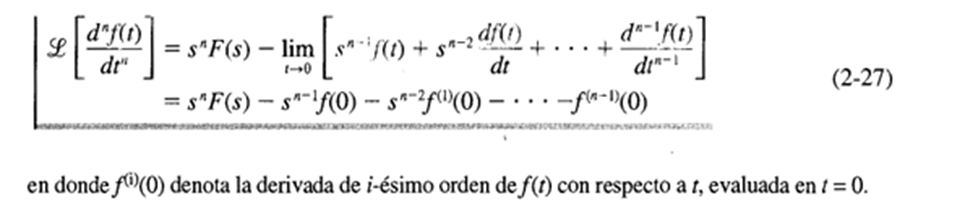

Se obtiene


$$s^2 Y\left(s\right)-\textrm{sy}\left(0\right)-y^1 \left(0\right)+3\textrm{sY}\left(s\right)-3y\left(0\right)+2Y\left(s\right)=\frac{5}{s}$$


#### PASO 2

Factorizando los términos de $Y\left(s\right)$ se obtiene la siguiente expresión:


$$Y\left(s\right)\left(s^2 +3s+2\right)=\frac{5}{s}+3y\left(0\right)+\textrm{sy}\left(0\right)+y^1 \left(0\right)$$


Dado que lo que nos interesa es obtener el comportamiento de $y\left(t\right)$ en el dominio del tiempo procedemos a despejar la función en términos de $y\left(s\right)$ y reemplazando los valores inciales se obtiene


$$Y\left(s\right)=\frac{\frac{5}{s}-3-s+2}{\left(s^2 +3s+2\right)}$$


simplificando un poco:


$$Y\left(s\right)=\frac{\frac{5}{s}-1-s}{\left(s^2 +3s+2\right)}*\frac{s}{s}$$



$$Y\left(s\right)=\frac{-s^2 -s+5}{s\left(s^2 +3s+2\right)}$$


#### PASO 3

A continuación vamos a representar la función utilizando matlab:

syms s
numerator = [-1 -1 5];
denominator = [1 3 2 0];
Y_s = tf(numerator,denominator)


Y_s =
 
    -s^2 - s + 5
  -----------------
  s^3 + 3 s^2 + 2 s
 
Continuous-time transfer function.
Model Properties


Ahora procedemos a utilizar la función "residue" con el objetivo de obtener la descomposición en fracciones parciales de la función de transferencia:

[r,p,k] = residue(numerator,denominator)

r =     1.5000
   -5.0000
    2.5000


p =     -2
    -1
     0



k =

     []



La documentación de matlab nos dice que la fracción parcial se puede reescribir de la siguiente manera:

Y_s_fract=r(1)/(s-p(1))+r(2)/(s-p(2))+r(3)/(s-p(3))

$$Y\_s\_fract = \frac{3}{2\,\left(s+2\right)}-\frac{5}{s+1}+\frac{5}{2\,s}$$

#### PASO 4

A continuación obtendremos la transformada inversa de laplace


$$Y\left(s\right)=\frac{5}{2s}-\frac{5}{s+1}+\frac{3}{2\left(s+2\right)}$$



$$\ell \left\lbrace Y\left(s\right)=\frac{5}{2s}-\frac{5}{s+1}+\frac{3}{2\left(s+2\right)}\right\rbrace =\left\lbrace y\left(t\right)=\frac{5}{2}u\left(t\right)-5e^{-t} +\frac{3}{2}e^{-2t} \right\rbrace$$


Comprobamos utilizando la transformada inversa de laplace de matlab

syms t;
f = ilaplace(Y_s_fract, s, t)

$$f = \frac{3\,{\mathrm{e}}^{-2\,t}}{2}-5\,{\mathrm{e}}^{-t}+\frac{5}{2}$$

#### PASO 5 (Graficar)

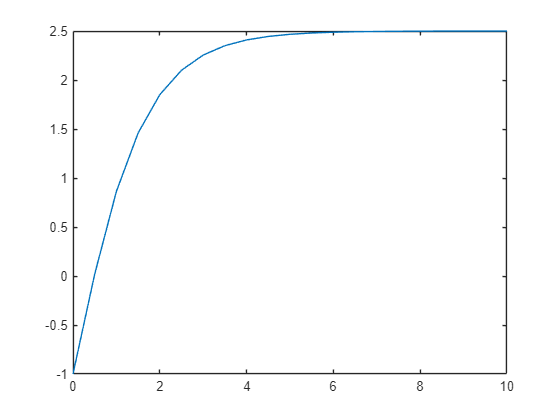

t = 0:0.5:10; 
y_t=(5/2)-(5*exp(-t))+((3/2)*exp(-2*t));
plot(t,y_t);

Observe que la solución es coherente con las condiciones iniciales 


$$\left\lbrack \begin{array}{c}
y\left(0\right)=-1\\
y^1 \left(0\right)=2
\end{array}\right\rbrack$$



$$y\left(0\right)=\frac{5}{2}u\left(0\right)-5e^{-0} +\frac{3}{2}e^{-2\left(0\right)}$$



$$y\left(0\right)=\frac{5}{2}-5+\frac{3}{2}=-1$$



$$y\left(\infty \right)=\frac{5}{2}-5e^{-\infty } +\frac{3}{2}e^{-2*\infty }$$



$$y\left(\infty \right)=\frac{5}{2}$$


#### Ejercicios

- Calcular la respuesta al escalón unitario para un circuito RC de primer orden, con valores $R=1\Omega$ y $C=1F$

- Resolver y gráficar (Asumir condiciones iniciales igual cero (0)


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }y\left(t\right)+5\frac{{\mathrm{d}}^1 }{\mathrm{d}t^1 }y\left(t\right)+4y\left(t\right)=e{\;}^{-2t} u\left(t\right)$$


- Encuentra las transformadas de Laplace de las siguientes funciones.